# 关于第二次编程作业的说明：

- 请注意完成编程作业中的讨论，可以通过注释、嵌入文本、额外文件等任意形式完成；

- 在第二次编程作业中如果使用工具箱，可以通过截图等形式提交结果；

- 为了简化大家的代码过程，我向大家提供了第二次编程作业的.mlx文件，里面提供了关于.mlx文件的说明以及部分同学在第一次编程作业中使用.mlx文件时遇到的图像错位问题；

- 大家仍然可以使用任意形式matlab代码完成第一次编程作业，并不限制大家一定需要使用该模版，但仍然需要大家注明题号；

感谢大家的配合！

# template

- 本文件已经对每道编程题目通过分节符分节，可以单独通过”运行节“命令执行一道题目（选中）的代码，或通过”运行“命令执行整个文件；

- 关于很多同学在.mlx中遇到的图像错位问题：主要原因是在单个脚本文件中，工作区和图像设定是始终向后保持的。在之前的题目中使用subplot()画多个子图，之后的题目中画图时会出现在之前的子图中，可以在每个题目的代码前通过clf命令清除图像窗口；

clear
clf

% (a)
x = 0:pi/100:2*pi;  
y = sin(x)

y =          0    0.0314    0.0628    0.0941    0.1253    0.1564    0.1874    0.2181    0.2487    0.2790    0.3090    0.3387    0.3681    0.3971    0.4258    0.4540    0.4818    0.5090    0.5358    0.5621    0.5878    0.6129    0.6374    0.6613    0.6845    0.7071    0.7290    0.7501    0.7705    0.7902    0.8090    0.8271    0.8443    0.8607    0.8763    0.8910    0.9048    0.9178    0.9298    0.9409    0.9511    0.9603    0.9686    0.9759    0.9823    0.9877    0.9921    0.9956    0.9980    0.9995


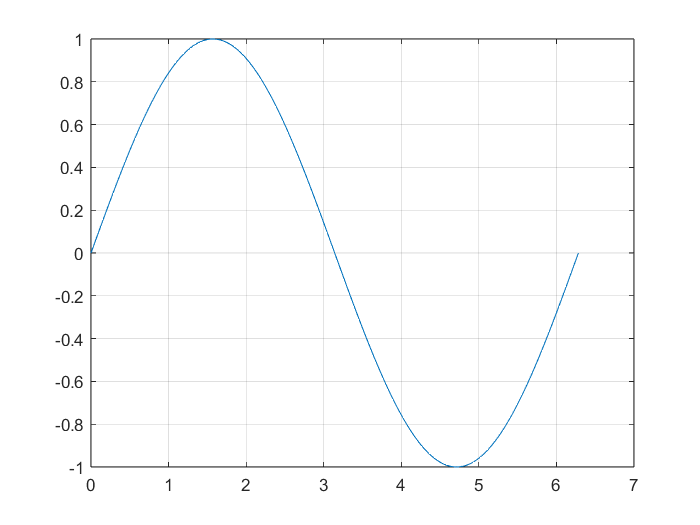

plot(x,y), grid;

% (b)
% 讨论分析

或通过内置文本讨论分析。如需插入公式，可以使用方程或LaTex方程 $F(s)=\int_0^\infty e^{-st} f(t) {\rm d}t$。

如需插入截图，直接粘贴即可。

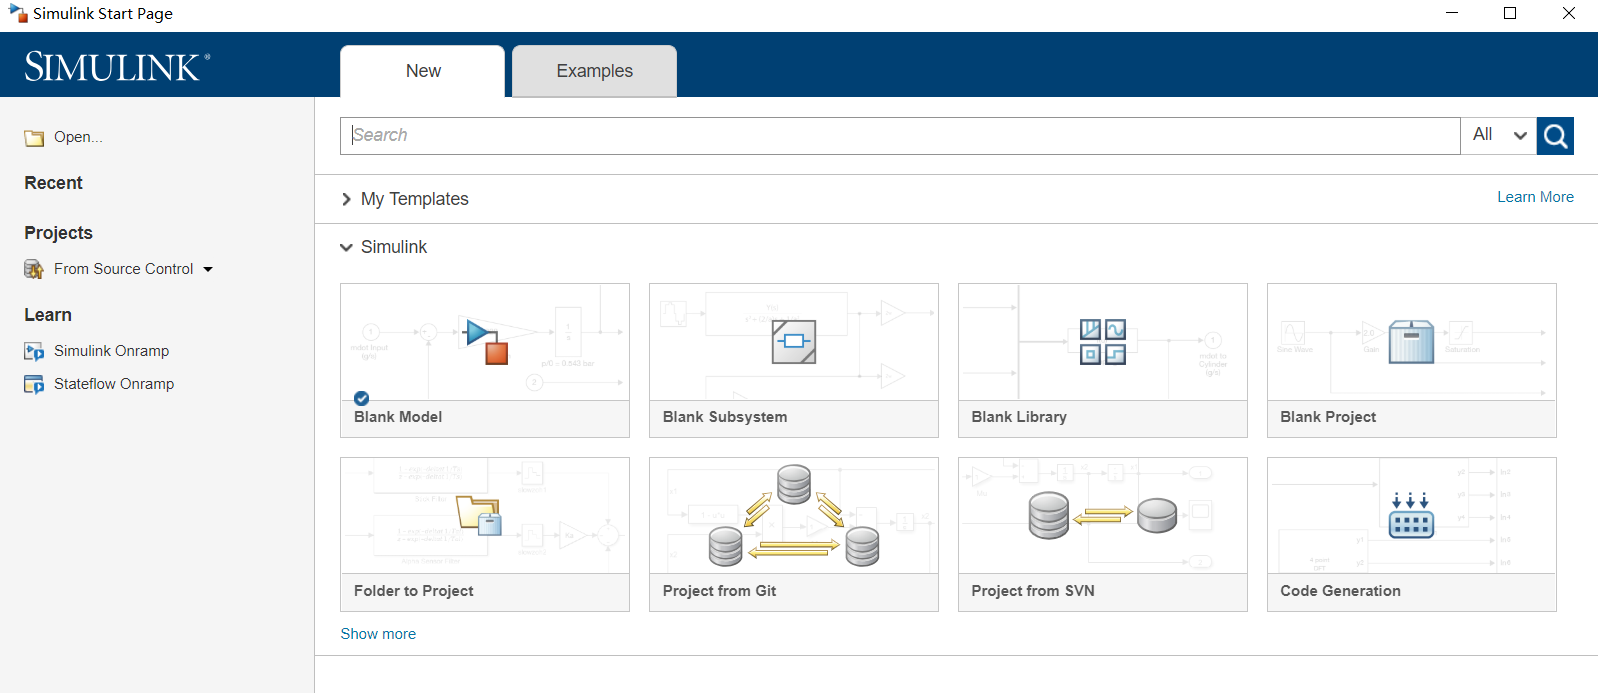

# 7-1

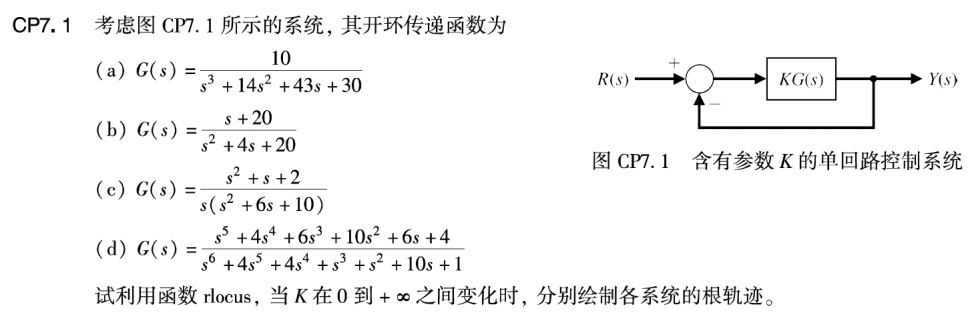

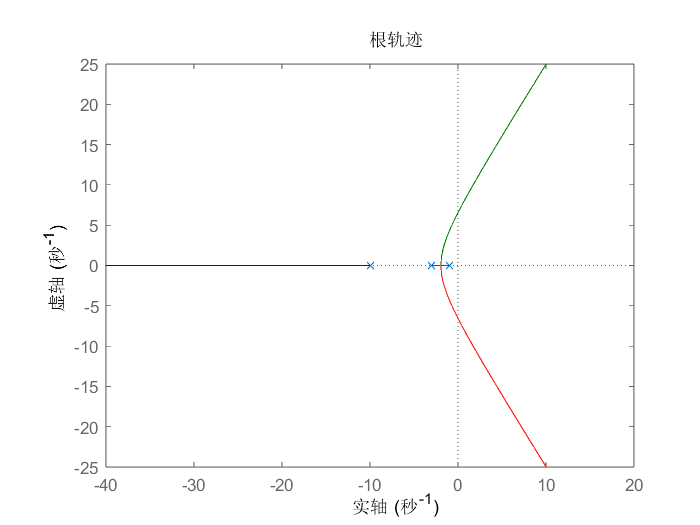

num1 = [10]; den1 = [1 14 43 30]; sys1 = tf(num1, den1);
rlocus(sys1);

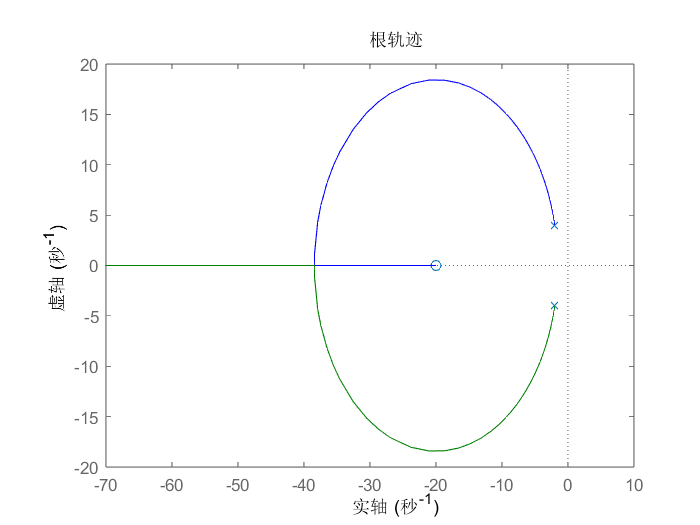

num2 = [1 20]; den2 = [1 4 20]; sys2 = tf(num2, den2);
rlocus(sys2);

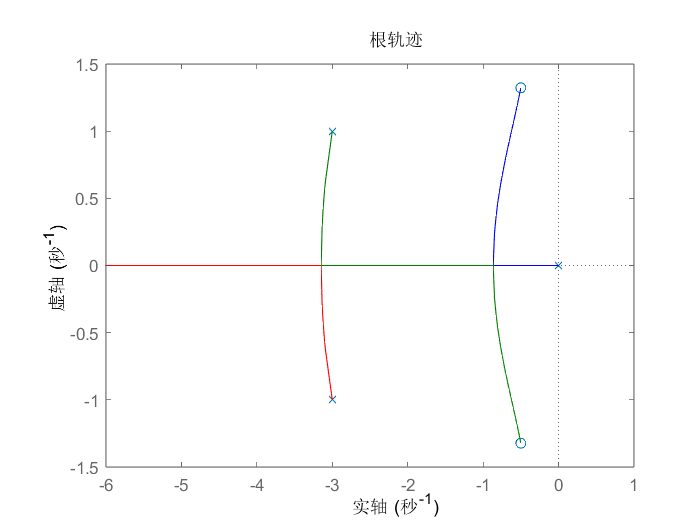

num3 = [1 1 2]; den3 = [1 6 10 0]; sys3 = tf(num3, den3);
rlocus(sys3);

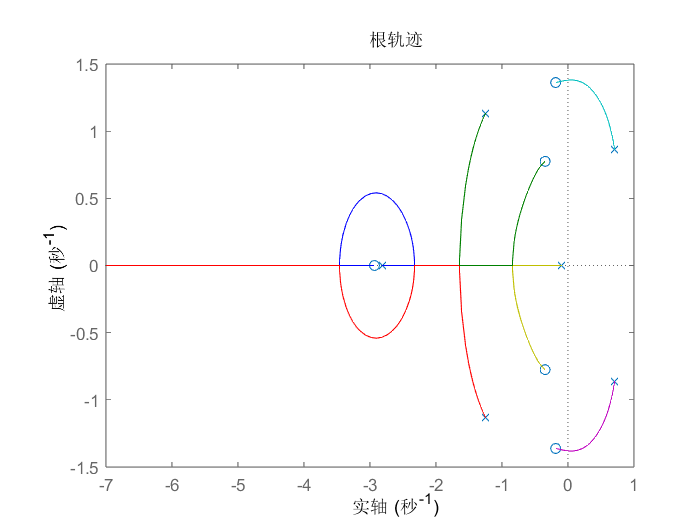

num4 = [1 4 6 10 6 4]; den4 = [1 4 4 1 1 10 1]; sys4 = tf(num4, den4);
rlocus(sys4);

# 7-2

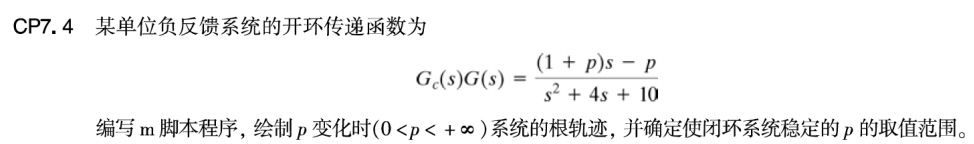

`等效的特征方程为:`


$$1+p\frac{s-1}{s^{2}+5s+10}=0$$


`使得闭环系统稳定的 p 的范围为`


$$0 < p < 10$$


num = [1 -1]; den = [1 5 10]; sys = tf(num, den)

sys =
 
      s - 1
  --------------
  s^2 + 5 s + 10
 
Continuous-time transfer function.



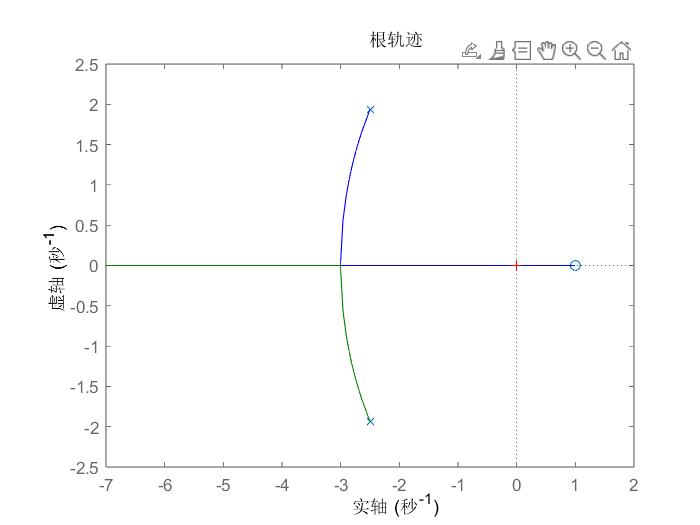

Select a point in the graphics window


selected_point = -0.0028 - 0.0248i

ans = 9.9546

rlocus(sys);
rlocfind(sys)

# 7-3

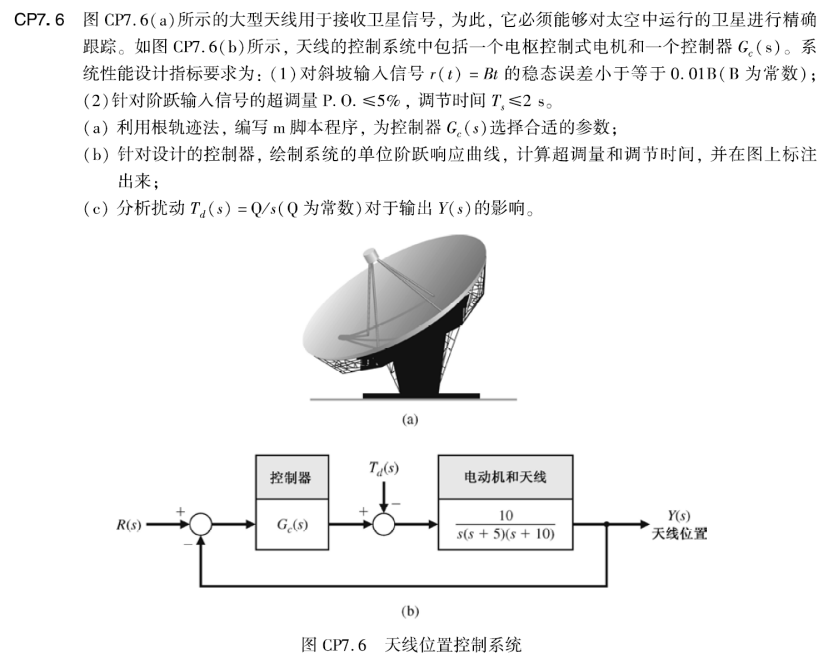

`我们选用具有两个实极点和两个实零点的控制器, 以满足题目的稳态误差要求.`

`其中特征方程为:`


$$1 + K\frac{(s+5.5)(s+0.01)}{(s+6.5)(s+0.0001)}\frac{10}{s^{3}+15s^{2}+50s} = 0$$


`对应的根轨迹如第一张图所示. 并且我们取增益`


$$K=8.58$$


`使得阶跃响应如图所示, 可以看出超调量和调节时间均满足要求. 其中静态速度误差常数`


$$k_v = 145.2$$


`意味着斜坡信号的稳态误差`


$$e_{ss} = 1 / k_v = 0.0069$$


`而对于扰动的影响, 如最后一张图所示, 阶跃函数作为输入的输出不再趋于 1, 而是趋于 0.`

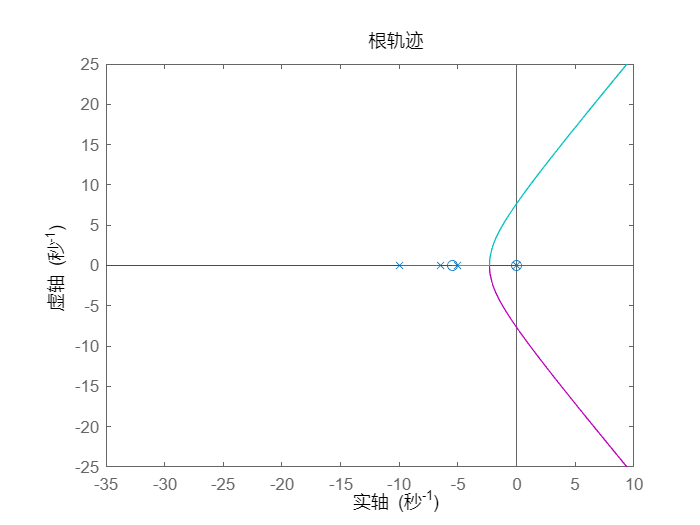

ng = 10; dg = conv([1 10 0], [1 5]); sysg = tf(ng, dg);
nh = conv([1 0.01], [1 5.5]);
dh = conv([1 6.5], [1 0.0001]); 
sysh = tf(nh, dh);
rlocus(sysg * sysh)

K = 8.58; sysh = tf(K * nh, dh);
sys = series(sysg, sysh);syscl = feedback(sys, 1)

syscl =
 
                 85.8 s^2 + 472.8 s + 4.719
  --------------------------------------------------------
  s^5 + 21.5 s^4 + 147.5 s^3 + 410.8 s^2 + 472.8 s + 4.719
 
Continuous-time transfer function.



stepinfo(syscl)

ans = 包含以下字段的 struct :
         RiseTime: 0.9496
    TransientTime: 1.5070
     SettlingTime: 1.5070
      SettlingMin: 0.9071
      SettlingMax: 1.0177
        Overshoot: 1.7656
       Undershoot: 0
             Peak: 1.0177
         PeakTime: 2.1252


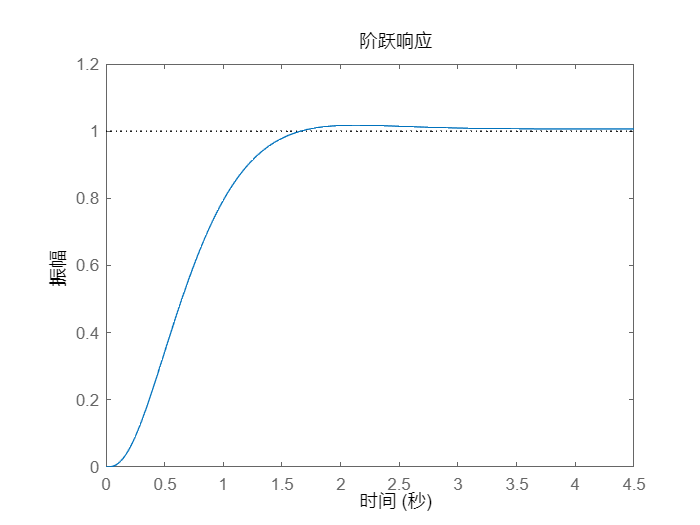

step(syscl);

Kv = 10 * 8.58 * 0.01 * 5.5 / 10 / 6.5 / 0.0001 / 5

Kv = 145.2000

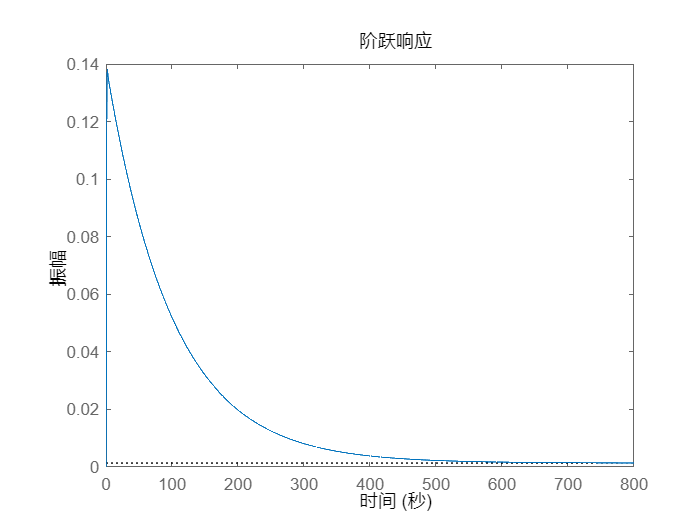

systd = feedback(sysg, sysh);
step(systd)

# 7-4

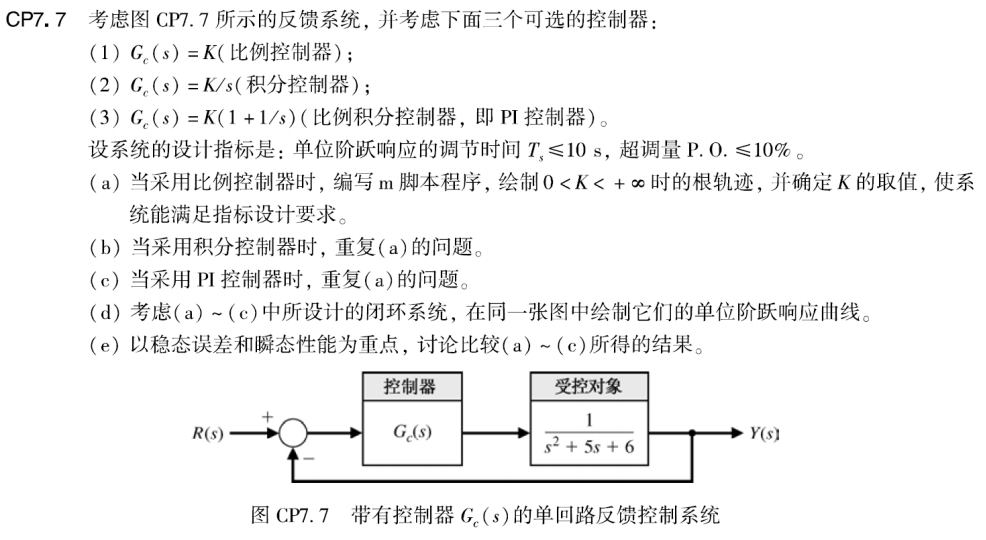

numg = [1]; deng = [1 5 6]; sysg = tf(numg,deng);
t = [0:0.1:15];
% (a)
sys1 = sysg;
rlocus(sys1), grid
hold on
plot([-0.4 -0.4],[-6 6],'--',...
[0 -6*tan(36.2*pi/180)],[0 6],'--',...
[0 -6*tan(36.2*pi/180)],[0 -6],'--')
hold off
[kp,poles] = rlocfind(sys1)

Select a point in the graphics window


selected_point = -2.5057 + 3.3648i

kp = 11.5717

poles =   -2.5000 + 3.3648i
  -2.5000 - 3.3648i


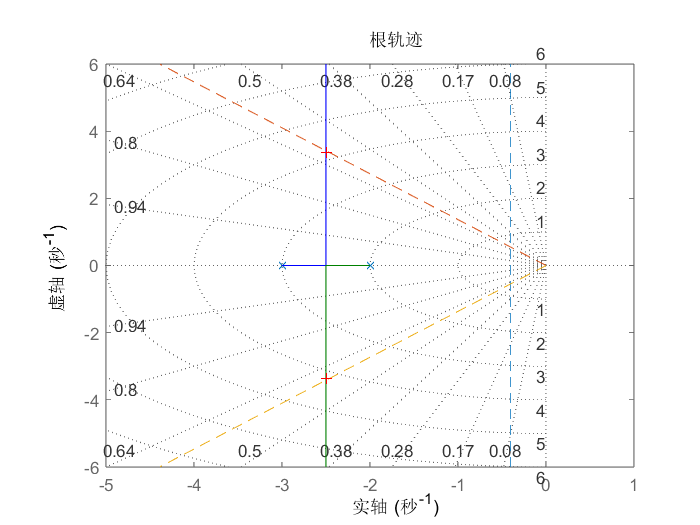

Select a point in the graphics window


selected_point = -0.6212 + 0.7940i

ki = 4.0228

poles =   -3.6613 + 0.0000i
  -0.6693 + 0.8067i
  -0.6693 - 0.8067i


% (b)
numc = [1]; denc = [1 0]; sysc = tf(numc,denc);
sys2 = series(sysc,sysg); 
figure
rlocus(sys2), grid
hold on
plot([-0.4 -0.4],[-6 6],'--',...
[0 -6*tan(36.2*pi/180)],[0 6],'--',...
[0 -6*tan(36.2*pi/180)],[0 -6],'--')
hold off
[ki,poles] = rlocfind(sys2)

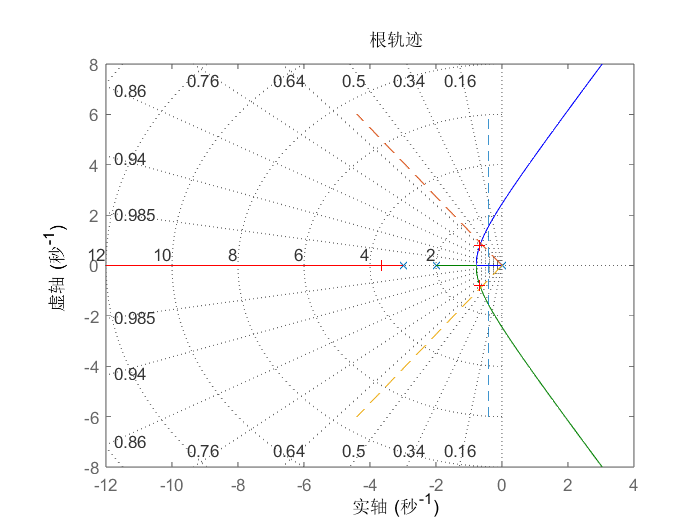

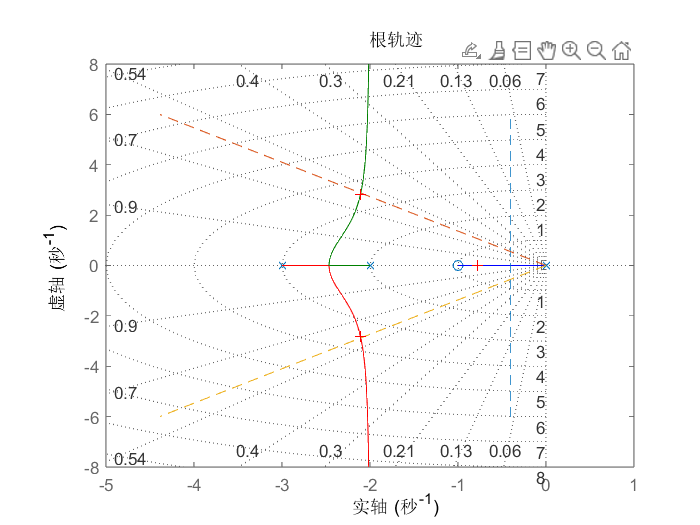

Select a point in the graphics window


selected_point = -2.1080 + 2.8189i

kpi = 9.6928

poles =   -2.1090 + 2.8189i
  -2.1090 - 2.8189i
  -0.7820 + 0.0000i


% (c)
figure
numc = [1 1]; denc = [1 0]; sysc = tf(numc,denc);
sys3 = series(sysc,sysg); 
rlocus(sys3), grid
hold on
plot([-0.4 -0.4],[-6 6],'--',...
[0 -6*tan(36.2*pi/180)],[0 6],'--',...
[0 -6*tan(36.2*pi/180)],[0 -6],'--')
hold off
[kpi,poles] = rlocfind(sys3)

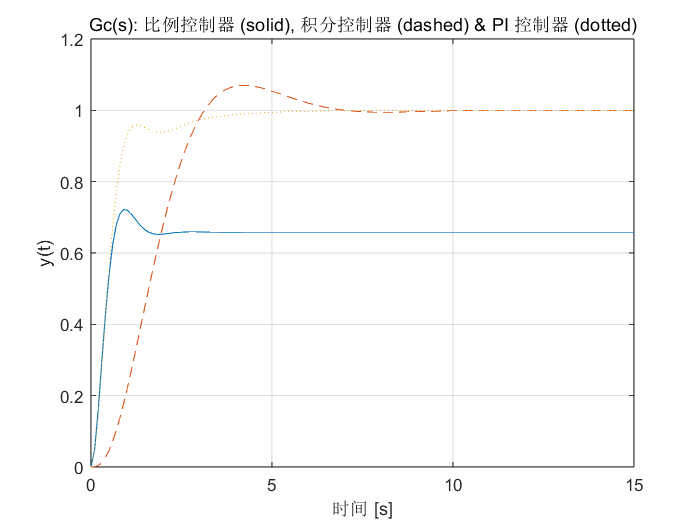

% (d)
figure
sys1_o = kp*sys1; sys1_cl = feedback(sys1_o,[1]);
sys2_o = ki*sys2; sys2_cl = feedback(sys2_o,[1]);
sys3_o = kpi*sys3; sys3_cl = feedback(sys3_o,[1]);
[y1,t] = step(sys1_cl,t);
[y2,t] = step(sys2_cl,t);
[y3,t] = step(sys3_cl,t);
plot(t,y1,t,y2,'--',t,y3,':'),grid
xlabel('时间 [s]'),ylabel('y(t)')
title('Gc(s): 比例控制器 (solid), 积分控制器 (dashed), PI 控制器 (dotted)')

% (d)

积分控制器和PI控制器的稳态误差优于比例控制器; 比例控制器和PI控制器的瞬态性能优于积分控制器.

总的来说就是PI控制器是最优的选择.

# 7-5

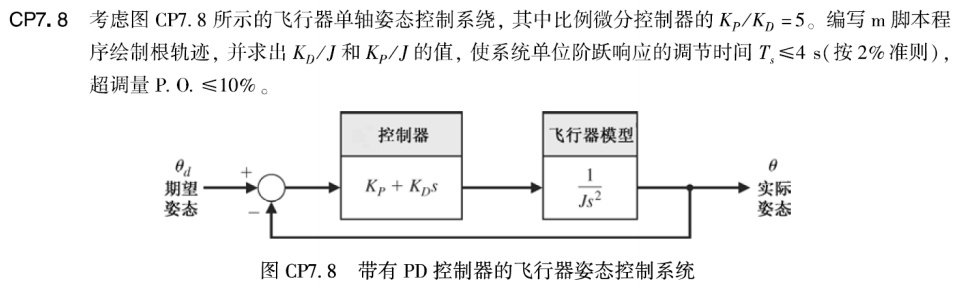

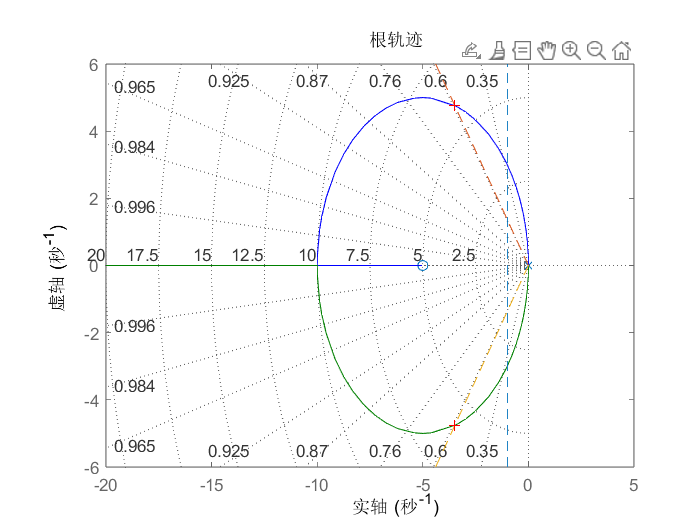

Select a point in the graphics window


selected_point = -3.5464 + 4.6749i

kpi = 7.0331

poles =   -3.5165 + 4.7749i
  -3.5165 - 4.7749i


num = [1 5]; den = [1 0 0]; sys = tf(num,den);
rlocus(sys), grid
hold on
plot([-1.0 -1.0],[-6 6],'--',...
[0 -6*tan(36.2*pi/180)],[0 6],'--',...
[0 -6*tan(36.2*pi/180)],[0 -6],'--')
hold off
[kpi,poles] = rlocfind(sys)

`由于传递函数为`


$$G_c(s)G(s) = \frac{K_1 + K_2s}{J s^{2}} = K \frac{s+5}{s^{2}}$$


`其中`


$$K = K_2 / J$$


`如图所示, 选择`


$$K = 7.0331$$


`因此有`


$$K_2 / J = 7.0331$$



$$K_1 / J = 35.1655$$


# 7-6

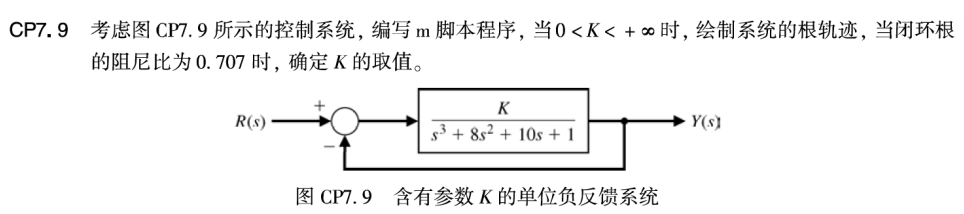

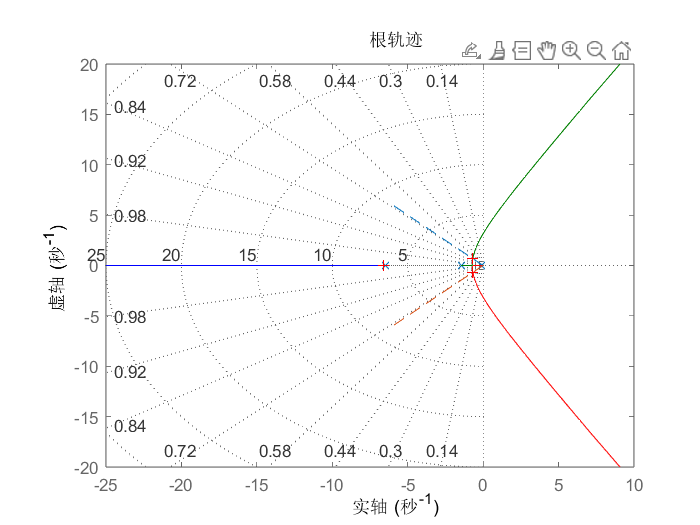

Select a point in the graphics window


selected_point = -0.7055 + 0.6948i

kpi = 5.2680

poles =   -6.6353 + 0.0000i
  -0.6824 + 0.6921i
  -0.6824 - 0.6921i


num = [1]; den = [1 8 10 1]; sys = tf(num, den);
rlocus(sys), grid
hold on
plot([0 -6*tan(45*pi/180)],[0 6],'--',...
[0 -6*tan(45*pi/180)],[0 -6],'--')
hold off
[kpi,poles] = rlocfind(sys)

因此我们选择 $K = 5.2$

# 3-1

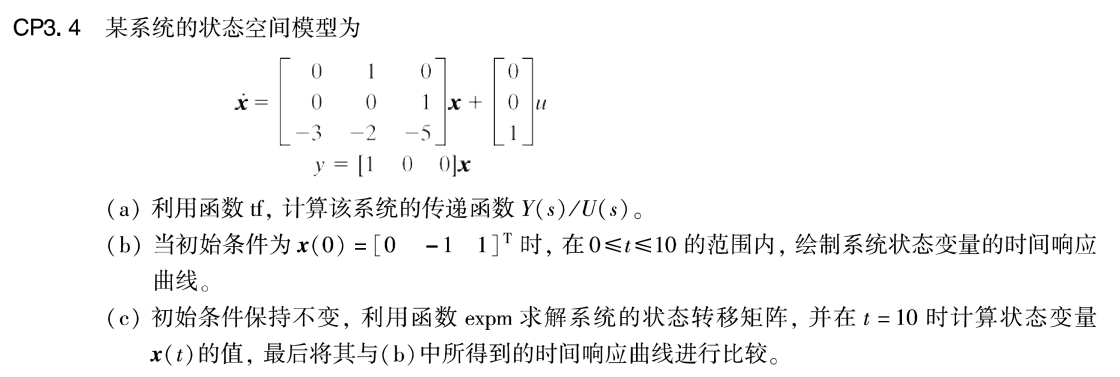

a=[0 1 0; 0 0 1; -3 -2 -5];
b=[0;0;1];
c=[1 0 0];
d=[0];
% (a)
sys_ss = ss(a,b,c,d)

sys_ss =
 
  A = 
       x1  x2  x3
   x1   0   1   0
   x2   0   0   1
   x3  -3  -2  -5
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
连续时间状态空间模型。



sys_tf = tf(sys_ss)

sys_tf =
 
            1
  ---------------------
  s^3 + 5 s^2 + 2 s + 3
 
Continuous-time transfer function.



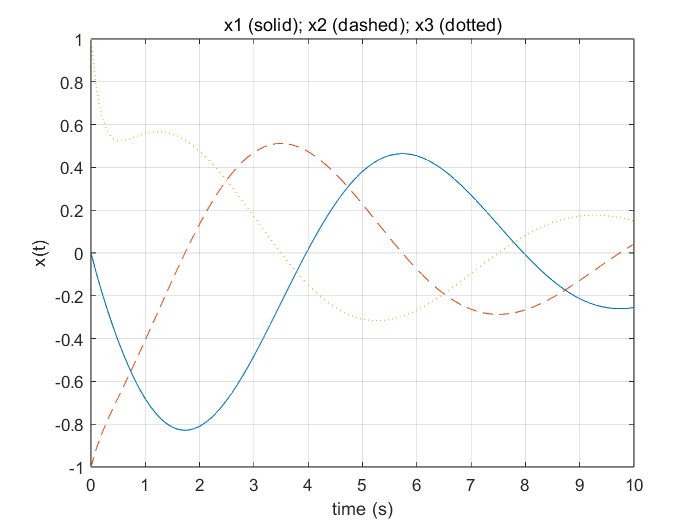

% (b)
x0 = [0 -1 1];
t = [0:0.1:10];
u = 0*t;
[y,t,x] = lsim(sys_ss,u,t,x0);
plot(t,x(:,1),t,x(:,2),'--',t,x(:,3),':');
xlabel('time (s)'), ylabel('x(t)'), grid
title('x1 (solid); x2 (dashed); x3 (dotted)')

xf_sim = x(length(t),:)'

xf_sim =    -0.2545
    0.0418
    0.1500


% (c)
t1 = 10;
Phi = expm(a*t1);
xf_phi = Phi*x0'

xf_phi =    -0.2545
    0.0418
    0.1500


可以看见与用状态矩阵模拟的结果一致.

# 3-2

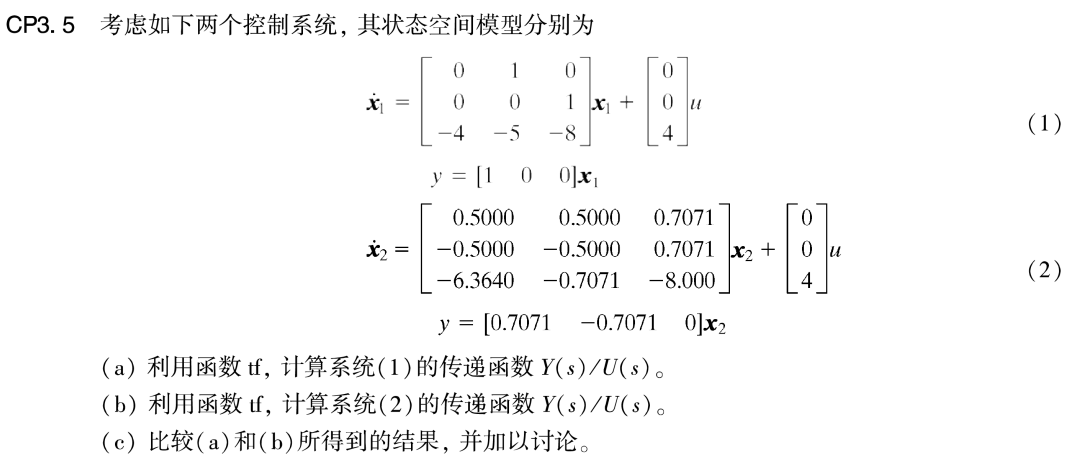

a1=[0 1 0; 0 0 1; -4 -5 -8];
b1=[0;0;4];
c1=[1 0 0];
d1=[0];
% (a)
sys_ss1 = ss(a1,b1,c1,d1);
sys_tf1 = tf(sys_ss1)

sys_tf1 =
 
            4
  ---------------------
  s^3 + 8 s^2 + 5 s + 4
 
Continuous-time transfer function.



% (b)
a2=[ 0.5000 0.5000 0.7071;
 -0.5000 -0.5000 0.7071;
 -6.3640 -0.7071 -8.0000];
b2=[0;0;4];
c2=[0.7071 -0.7071 0];
d2=[0];
sys_ss2 = ss(a2,b2,c2,d2);
sys_tf2 = tf(sys_ss2)

sys_tf2 =
 
            4
  ---------------------
  s^3 + 8 s^2 + 5 s + 4
 
Continuous-time transfer function.



% (c)

我们可以看见, (a) 和 (b) 中的状态空间模型不同, 却能对应同一个传递函数.

这说明了同一个传递函数可以有着不同的状态空间模型.

# 3-3

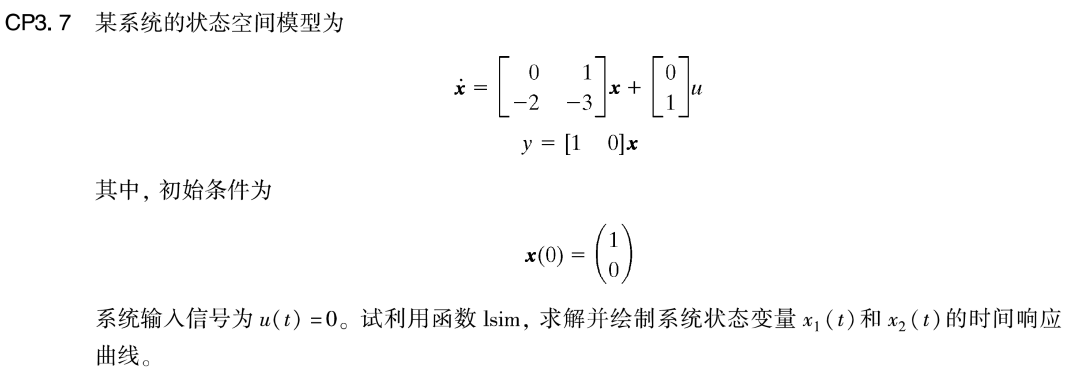

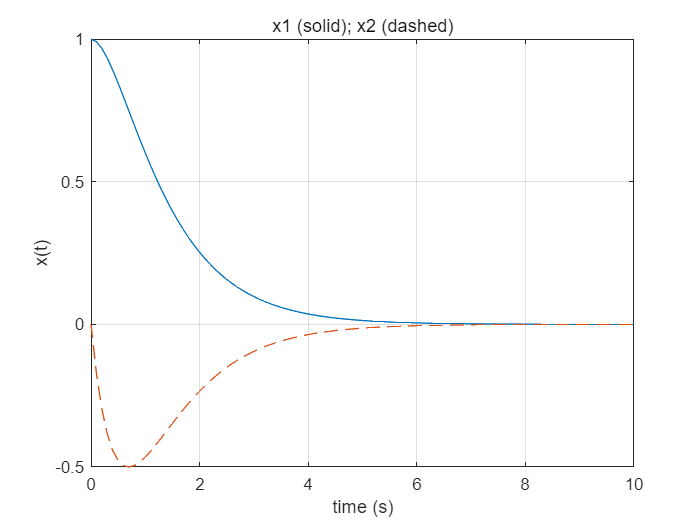

a=[0 1;-2 -3]; b=[0;1]; c=[1 0]; d=[0];
sys = ss(a,b,c,d);
x0=[1;0];
t=[0:0.1:10]; u=0*t;
[y,t,x]=lsim(sys,u,t,x0);
plot(t,x(:,1),t,x(:,2),'--')
xlabel('time (s)'), ylabel('x(t)'), grid
title('x1 (solid); x2 (dashed)')

# 11-1

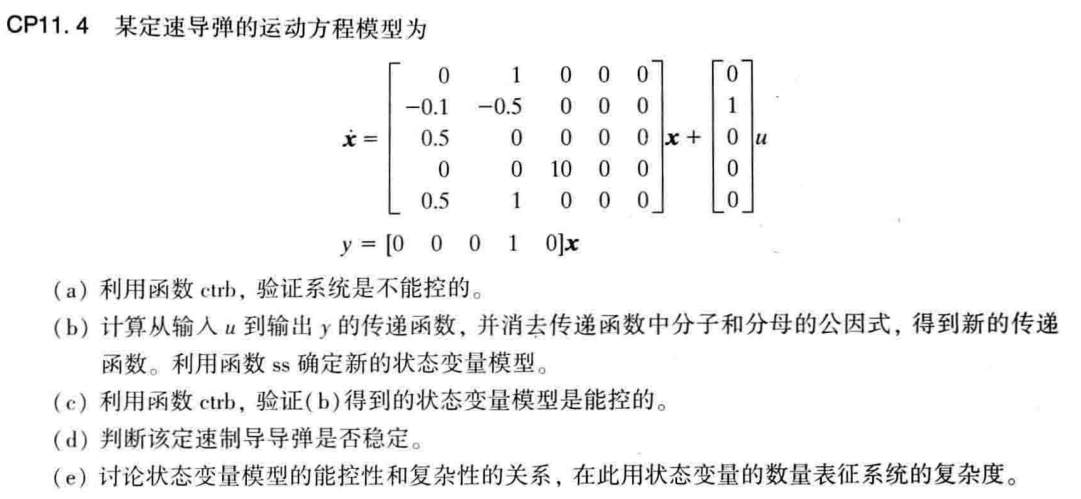

a=[0 1 0 0 0;-0.1 -0.5 0 0 0;0.5 0 0 0 0;0 0 10 0 0;0.5 1 0 0 0];
b=[0;1;0;0;0];
c=[0 0 0 1 0];
d=[0];
sys_ss = ss(a,b,c,d);
% (a)
Pc = ctrb(sys_ss);
dt_Pc = det(Pc)

dt_Pc = 0

% (b)
sys_tf = tf(sys_ss)

sys_tf =
 
             5
  -----------------------
  s^4 + 0.5 s^3 + 0.1 s^2
 
Continuous-time transfer function.



sys_new = minreal(sys_tf);
sys_new_ss = ss(sys_new)

sys_new_ss =
 
  A = 
         x1    x2    x3    x4
   x1  -0.5  -0.1     0     0
   x2     1     0     0     0
   x3     0     1     0     0
   x4     0     0     1     0
 
  B = 
       u1
   x1   2
   x2   0
   x3   0
   x4   0
 
  C = 
        x1   x2   x3   x4
   y1    0    0    0  2.5
 
  D = 
       u1
   y1   0
 
连续时间状态空间模型。



% (c)
Pc_new = ctrb(sys_new_ss);
dt_Pc_new = det(Pc_new)

dt_Pc_new = 16

% (d)

由于在原点存在着两个极点, 因此系统不稳定.

% (e)

原来的系统有着太多的状态, 因此不可控.

当我们消除掉不必要的状态, 将状态数从 5 个降低到 4 个时, 系统就变得可控了.

# 11-2

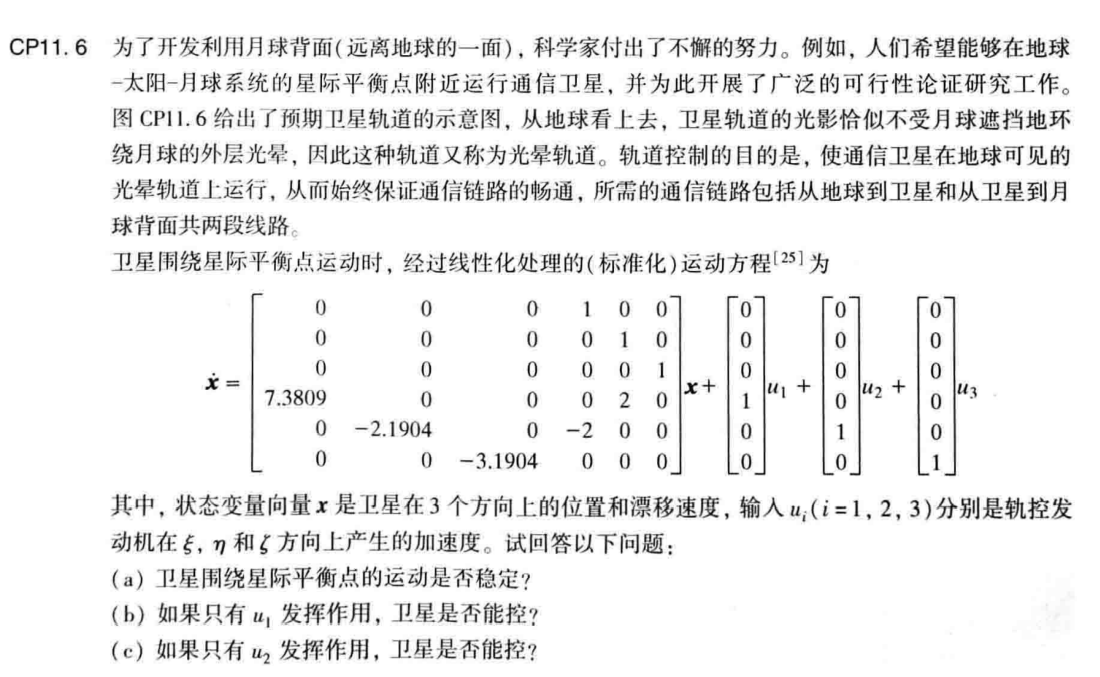 

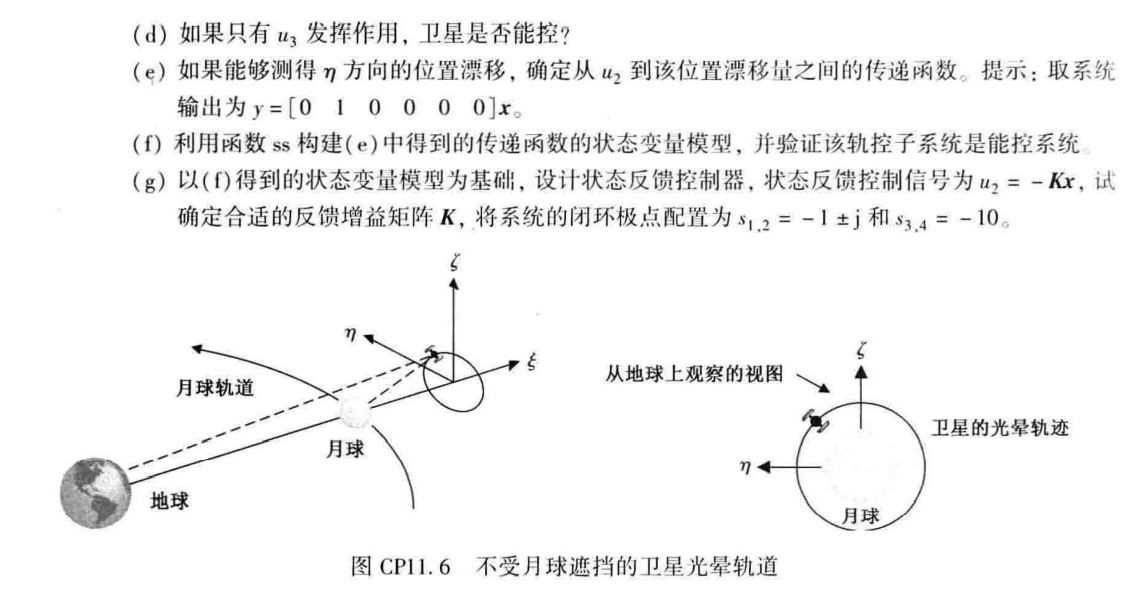

a = [0 0 0 1 0 0; 0 0 0 0 1 0; 0 0 0 0 0 1; 7.3809 0 0 0 2 0; 0 -2.1904 0 -2 0 0; 0 0 -3.1904 0 0 0];
c = [0 1 0 0 0 0];
d = [0];
b1 = [0; 0; 0; 1; 0; 0];
b2 = [0; 0; 0; 0; 1; 0];
b3 = [0; 0; 0; 0; 0; 1];
sys_ss_1 = ss(a,b1,c,d);
sys_ss_2 = ss(a,b2,c,d);
sys_ss_3 = ss(a,b3,c,d);
% (a)
evalues = eig(a)

evalues =   -2.1587 + 0.0000i
   2.1587 + 0.0000i
   0.0000 + 1.8626i
   0.0000 - 1.8626i
   0.0000 + 1.7862i
   0.0000 - 1.7862i


并不稳定.

% (b)
Pc1 = ctrb(sys_ss_1); dt1 = det(Pc1)

dt1 = 0

不能控.

% (c)
Pc2 = ctrb(sys_ss_2); dt2 = det(Pc2)

dt2 = 0

不能控.

% (d)
Pc3 = ctrb(sys_ss_3); dt3 = det(Pc3)

dt3 = 0

不能控.

% (e)
sys_tf = tf(sys_ss_2);
sys_tf = minreal(sys_tf)

sys_tf =
 
                s^2 + 4.441e-16 s - 7.381
  -----------------------------------------------------
  s^4 - 4.441e-16 s^3 - 1.191 s^2 - 1.541e-15 s - 16.17
 
Continuous-time transfer function.



% (f)
sys_ss = ss(sys_tf );
Pc = ctrb(sys_ss); dt_Pc = det(Pc)

dt_Pc = 64

由于行列式不等于零, 系统可控.

% (g)
P = [-1+i; -1-i;-10;-10];
[a, b] = ssdata(sys_ss);
K = acker(a,b,P)

K =    22.0000   71.5953   60.0000   27.0209


# 11-3

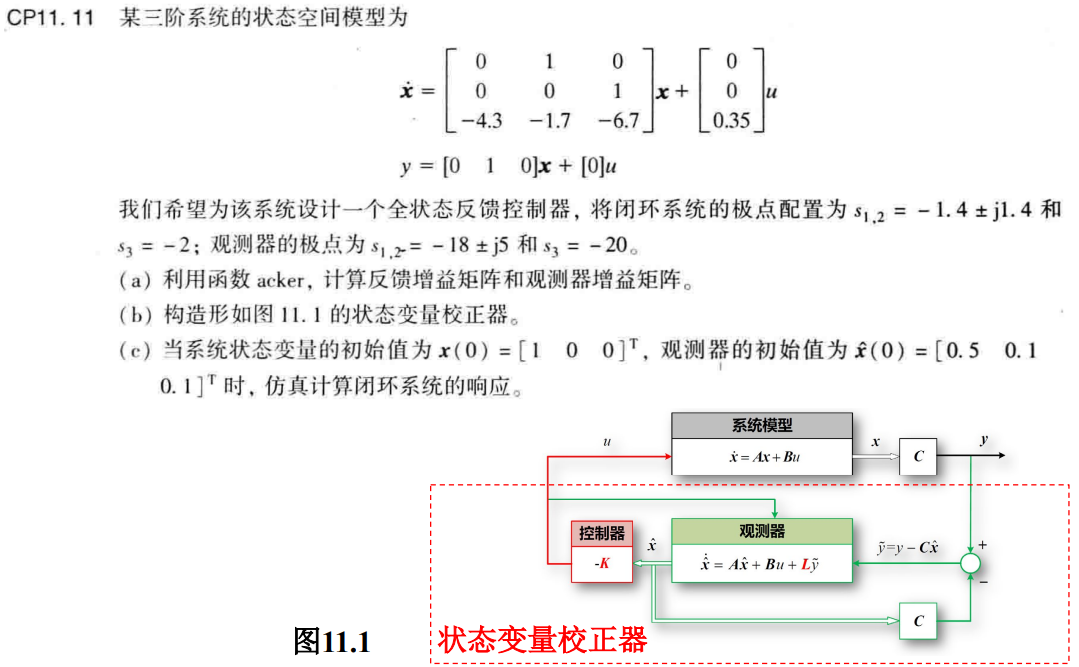

A=[0 1 0;0 0 1;-4.3 -1.7 -6.7]; B=[0;0;0.35]; C=[0 1 0]; D=[0];
% (a)
% 反馈增益矩阵
p=[-1.4+1.4*j;-1.4-1.4*j;-2];
K=acker(A,B,p)

K =    10.1143   22.3429   -5.4286


% 观测器增益矩阵
q=[-18+5*j;-18-5*j;-20];
L = acker(A',C',q); L=L'

L = 1.0e+03 *

   -1.6223
    0.0493
    0.7370


% (b)
Ac=[A -B*K;L*C A-B*K-L*C]; 
Bc=[zeros(6,1)];
Cc=eye(6); 
Dc=zeros(6,1);
sys=ss(Ac,Bc,Cc,Dc);
sys

sys =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       1       0       0       0       0
   x2       0       0       1       0       0       0
   x3    -4.3    -1.7    -6.7   -3.54   -7.82     1.9
   x4       0   -1622       0       0    1623       0
   x5       0    49.3       0       0   -49.3       1
   x6       0     737       0   -7.84  -746.5    -4.8
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
   y5   0
   y6   0
 
连续时间状态空间模型。



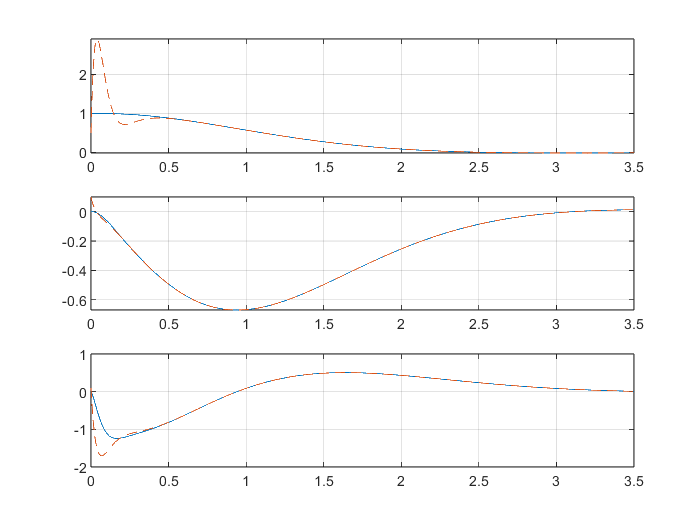

% (c)
x0=[1;0;0;0.5;0.1;0.1]; t=[0:0.001:3.5];
[y,t]=initial(sys,x0,t);
subplot(311)
plot(t,y(:,1),t,y(:,4),'--'), grid
subplot(312)
plot(t,y(:,2),t,y(:,5),'--'), grid
subplot(313)
plot(t,y(:,3),t,y(:,6),'--'), grid

# 13-1

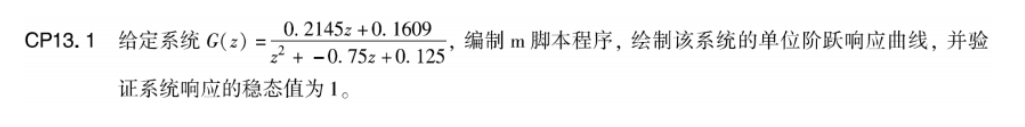

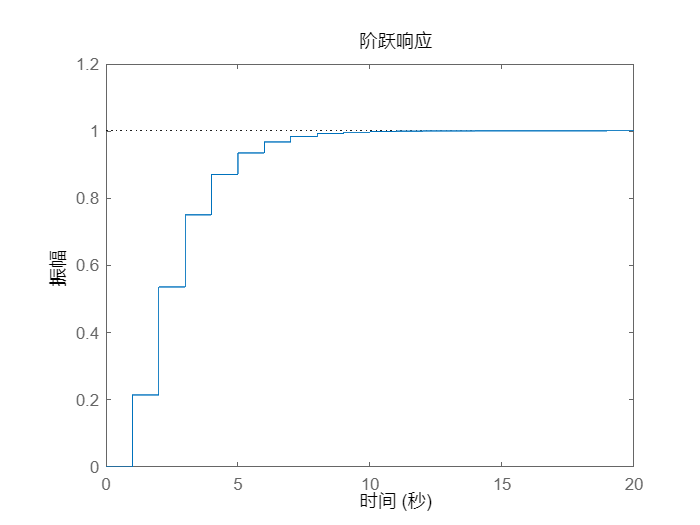

figure
num =[ 0.2145 0.1609]; den = [1 -0.75 0.125];
t = 0:1:50;
T = 1;
sysd = tf(num,den,T);
step(sysd)

可以看出系统相应的稳态值为 1.

# 13-2

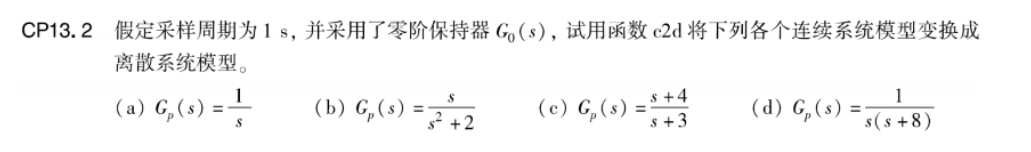

% (a)
num1 = [1]; den1 = [1 0]; T1 = 1;
sys1 = tf(num1,den1);
sys_d1 = c2d(sys1,T1,'zoh')

sys_d1 =
 
    1
  -----
  z - 1
 
采样时间: 1 seconds
离散时间传递函数。



% (b)
num2 = [1 0]; den2 = [1 0 2]; T2 = 1;
sys2 = tf(num2,den2);
sys_d2 = c2d(sys2,T2,'zoh')

sys_d2 =
 
  0.6985 z - 0.6985
  ------------------
  z^2 - 0.3119 z + 1
 
采样时间: 1 seconds
离散时间传递函数。



% (c)
num3 = [1 4]; den3 = [1 3]; T3 = 1;
sys3 = tf(num3,den3);
sys_d3 = c2d(sys3,T3,'zoh')

sys_d3 =
 
   z + 0.267
  -----------
  z - 0.04979
 
采样时间: 1 seconds
离散时间传递函数。



% (d)
num4 = [1]; den4 = [1 8 0]; T4 = 1;
sys4 = tf(num4,den4);
sys_d4 = c2d(sys4,T4,'zoh')

sys_d4 =
 
  0.1094 z + 0.01558
  -------------------
  z^2 - z + 0.0003355
 
采样时间: 1 seconds
离散时间传递函数。



# 13-3

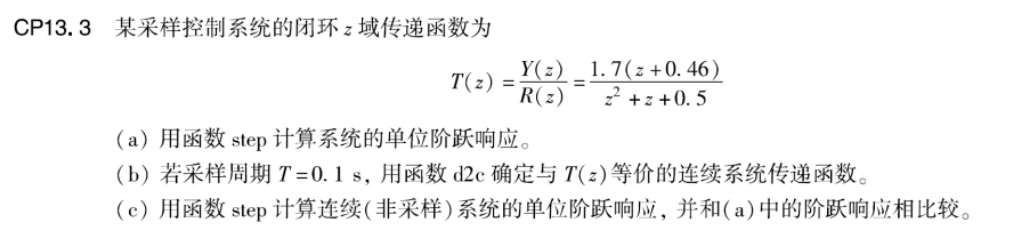

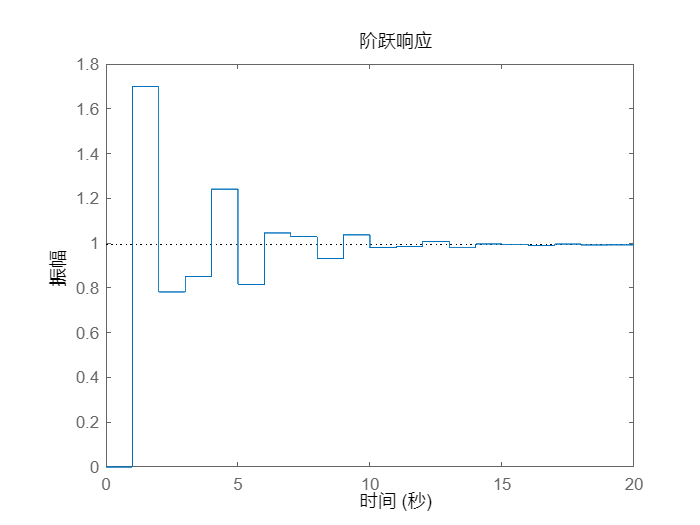

% (a)
num = 1.7 * [1 0.46]; den = [1 1 0.5];
T = 1;
t = 0:1:20;
sysd = tf(num,den,T);
step(sysd, t)

% (b)
num = 1.7 * [1 0.46]; den = [1 1 0.5];
T = 0.1;
t = 0:0.01:2;
sysd = tf(num,den,T);
sys = d2c(sysd,'zoh')

sys =
 
     13.37 s + 563.1
  ---------------------
  s^2 + 6.931 s + 567.2
 
Continuous-time transfer function.



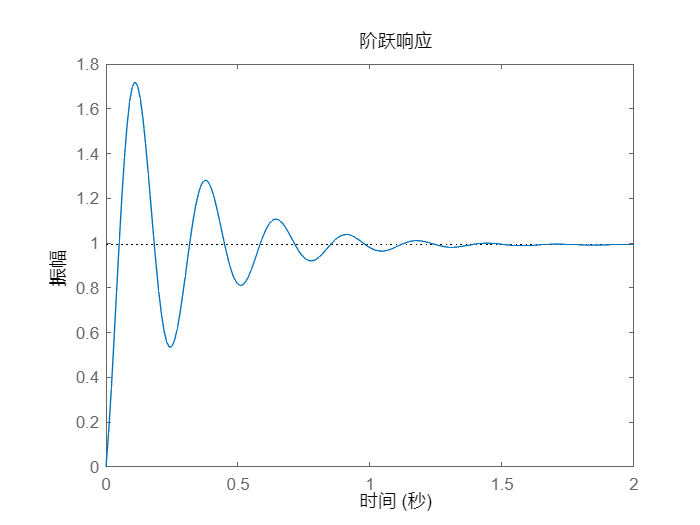

% (c)
step(sys, t)

可以看出, 与 (a) 中波形大体一致, 只不过更为平滑.